% clear mypi;
% clear;
% mypi=raspi("192.168.43.6","Kollis","646djohr");

% %%% 31250 sampler = 1 sek
% system(mypi,'lab4/./radar_sampler 125000 /home/Kollis/lab4/SAMPLE.bin','sudo');
% getFile(mypi,'/home/Kollis/lab4/SAMPLE.bin','C:\GitHub\TTT4280-Sensorer\Lab4');
% deleteFile(mypi, '/home/Kollis/lab4/SAMPLE.bin');

channels=2;
nBits=12;
VDD=3.3;
f_radar=24.13*10^9;
c=3*10^8;
j=sqrt(-1);

fid=fopen("Data/V34-Bort.bin","rb");
nomPeriod=fread(fid,1,"double");
nomPeriod = nomPeriod * 1e-6;
data=fread(fid,"uint16");
nSamples=numel(data)/channels; 
fs=1/nomPeriod;
dataMatrix = reshape(data,channels,nSamples);
fclose(fid);

n=0:nSamples-1;
t=n*nomPeriod;

h=transpose(hann(nSamples));
I=(dataMatrix(1,:))*VDD/(2.^nBits); 
Q=(dataMatrix(2,:))*VDD/(2.^nBits); 
I=I-mean(I); I(1)=0;
Q=Q-mean(Q); Q(1)=0;

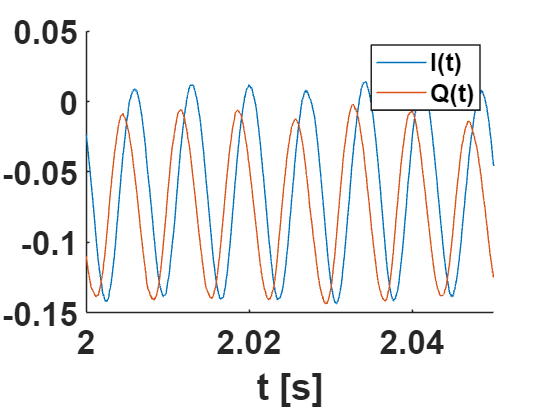

figure;
hold on;
plot(t,I);
plot(t,Q);
hold off;
xlabel("t [s]"); xlim([2 2.05]);
legend("I(t)","Q(t)",'Fontsize',15);
ax = gca;
ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';

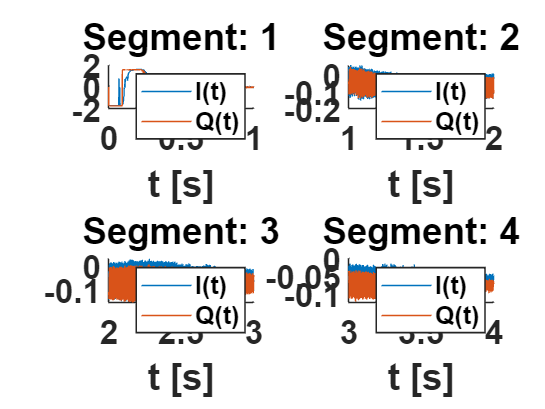

ax =   Axes (Segment: 1) with properties:

             XLim: [0 1]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


ax =   Axes (Segment: 2) with properties:

             XLim: [1 2]
             YLim: [-0.2000 0.0619]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.5838 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


ax =   Axes (Segment: 3) with properties:

             XLim: [2 3]
             YLim: [-0.1540 0.0273]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


ax =   Axes (Segment: 4) with properties:

             XLim: [3 4]
             YLim: [-0.1500 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


nSplit = 4; 
I_split = split_signal(I, nSplit);
Q_split = split_signal(Q, nSplit);
t_split = split_signal(t, nSplit);

nRows = ceil(sqrt(nSplit));
nCols = ceil(nSplit / nRows);

figure;
for i = 1:nSplit
    subplot(nRows, nCols, i);
    hold on;
    plot(t_split{i},I_split{i});
    plot(t_split{i},Q_split{i});
    hold off;
    xlabel("t [s]");
    title("Segment: " + i);
    legend("I(t)","Q(t)",'Fontsize',15);
    ax = gca
    ax.LineWidth = 1;
    ax.FontSize=20;
    ax.FontWeight='bold';
end

x=h.*(I+j*Q);
x=highpass(x,10,fs);
x=lowpass(x,4800,fs);
N_fft=pow2(ceil(log2(nSamples/nSplit)));
x_split=split_signal(x,nSplit);

X_segmented = zeros(nSplit, N_fft); 
for i = 1:nSplit
    X_segmented(i, :) = abs(fftshift(fft(x_split{i}, N_fft)));
end

S_segmented=20*log10(X_segmented);
f=1/(N_fft*nomPeriod)*(-N_fft/2:N_fft/2-1);

v_rad = zeros(1, nSplit);
f_d = zeros(1, nSplit);
f_d_idx = zeros(1, nSplit);
snr_I = zeros(1, nSplit);
snr_Q = zeros(1, nSplit);

for i = 1:nSplit
    [max_amp, max_idx] = max(X_segmented(i, :));
    f_d(i) = f(max_idx);
    f_d_idx(i)=max_idx;
    
    if abs(f_d(i)) < 10
        v_rad(i) = 0;
    else
        v_rad(i) = c * f_d(i) / (2 * f_radar);
    end
    
    snr_I(i) = snr(I_split{i});
    snr_Q(i) = snr(Q_split{i});
end
v_mean=mean(v_rad);

disp(['Gjennomsnitthastighet: ', num2str(v_mean),' m/s']);

Gjennomsnitthastighet: -0.88332 m/s


disp('Resultater for hvert segment:');

Resultater for hvert segment:


disp('-----------------------------');

-----------------------------


for i = 1:nSplit
    disp(['Segment ', num2str(i)]);
    disp(['Radiell hastighet: ', num2str(v_rad(i)), ' m/s']);
    disp(['Dopplerskift: ', num2str(f_d(i)), ' Hz']);
    disp(['SNR I: ', num2str(snr_I(i))]);
    disp(['SNR Q: ', num2str(snr_Q(i))]);
    disp('---------------------');
end

Segment 1


Radiell hastighet: -0.88332 m/s


Dopplerskift: -142.0975 Hz


SNR I: 6.1638


SNR Q: 7.7579


---------------------


Segment 2


Radiell hastighet: -0.8774 m/s


Dopplerskift: -141.1438 Hz


SNR I: 12.4852


SNR Q: 12.4406


---------------------


Segment 3


Radiell hastighet: -0.88925 m/s


Dopplerskift: -143.0511 Hz


SNR I: 21.3523


SNR Q: 20.8791


---------------------


Segment 4


Radiell hastighet: -0.88332 m/s


Dopplerskift: -142.0975 Hz


SNR I: 14.7946


SNR Q: 14.378


---------------------


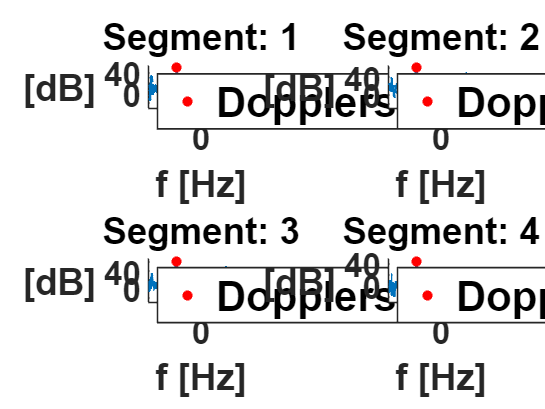

ax =   Axes (Segment: 1) with properties:

             XLim: [-298.4047 298.4047]
             YLim: [-30 56.6021]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


ax =   Axes (Segment: 2) with properties:

             XLim: [-296.4020 296.4020]
             YLim: [-30 68.5321]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.5838 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


ax =   Axes (Segment: 3) with properties:

             XLim: [-300.4074 300.4074]
             YLim: [-30 68.5875]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


ax =   Axes (Segment: 4) with properties:

             XLim: [-298.4047 298.4047]
             YLim: [-30 49.9100]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


figure;
for i = 1:nSplit
    subplot(nRows, nCols, i);
    hold on;
    plot(f,S_segmented(i,:),'LineWidth',2);
    plot(f_d(i),S_segmented(i,f_d_idx(i)),'*','LineWidth',2,'Color','r');
    xlabel("f [Hz]")
    ylabel("[dB]");
    title("Segment: " + i);
    xlim([-2.1*abs(f_d(i)) 2.1*abs(f_d(i))]); 
    ylim([-30 1.1*S_segmented(i,f_d_idx(i))]);
    legend("","Dopplerskift: "+round(f_d(i),1)+"Hz",'Fontsize',25,'Location','southwest');
    ax = gca
    ax.LineWidth = 1;
    ax.FontSize=20;
    ax.FontWeight='bold';
    set(get(gca,'ylabel'),'rotation',0);
end

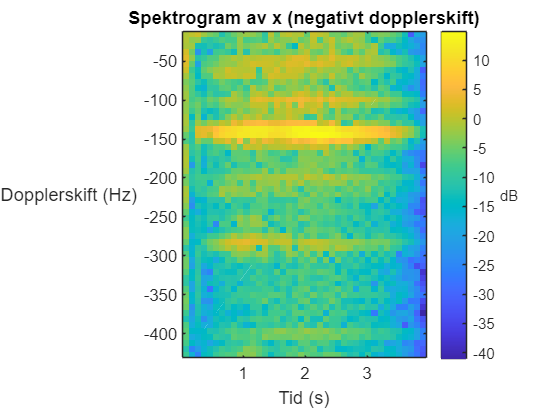

% Beregn gjennomsnittlig dopplerskift
f_d_mean = mean(f_d);

% Bestem retningen basert på gjennomsnittlig dopplerskift
if f_d_mean < 0
    doppler_direction = 'negativ';
else
    doppler_direction = 'positiv';
end

window_length = 4096;
overlap = window_length / 4;
% Beregn spektrogrammet
[s, f_spec, t_spec] = spectrogram(x, window_length, overlap, [], fs);

freq_range = [10, 3*max(abs(f_d))];
freq_idx = f_spec >= freq_range(1) & f_spec <= freq_range(2);
f_spec = f_spec(freq_idx);
s = s(freq_idx, :);
v_spec = abs(f_spec) * c / (2 * f_radar);

% Plot spektrogrammet med dopplerskift på y-aksen
figure;
if strcmp(doppler_direction, 'negativ')
    imagesc(t_spec, -f_spec, 10*log10(abs(s))); % Inverterer y-aksen for negativ dopplerskift
else
    imagesc(t_spec, f_spec, 10*log10(abs(s))); % Positiv dopplerskift
end
axis xy;
xlabel('Tid (s)');
ylabel('Dopplerskift (Hz)');
title(['Spektrogram av x (', doppler_direction, 't dopplerskift)']);
cb = colorbar;
ylabel(cb, 'dB');
set(get(cb,'ylabel'),'rotation',0);
set(get(gca,'ylabel'),'rotation',0);


% Plot spektrogrammet med radiell hastighet på y-aksen (positiv)
figure;
if strcmp(doppler_direction, 'negativ')
    imagesc(t_spec, -v_spec, 10*log10(abs(s))); % Inverterer y-aksen for negativ dopplerskift
else
    imagesc(t_spec, v_spec, 10*log10(abs(s))); % Positiv dopplerskift
end
axis xy;
xlabel('Tid (s)');
ylabel('Radiell hastighet (m/s)');
title(['Spektrogram av x (', doppler_direction, ' radiell hastighet)']);
cb = colorbar;
ylabel(cb, 'dB'); yticks(-10:0.2:10); %ylim([-6 0]);
set(get(cb,'ylabel'),'rotation',0);
set(get(gca,'ylabel'),'rotation',0); 
ax = gca

ax =   Axes (Spektrogram av x (negativ radiell hastighet)) with properties:

             XLim: [0.0164 3.9485]
             YLim: [-2.6796 -0.0711]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.3098 0.1100 0.5004 0.8150]
            Units: 'normalized'

  Show all properties


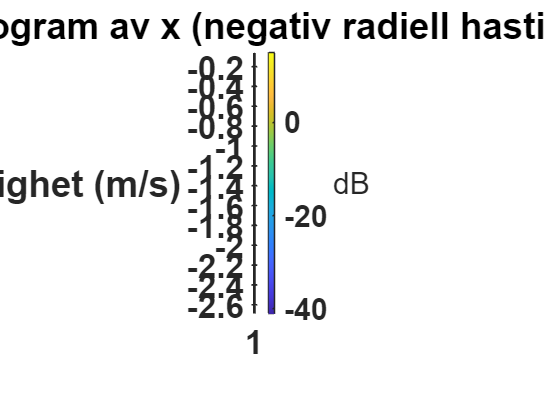

ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';